# Lab03 - Assignment

#### Student Nr:    

#### Name, Lastname:   

## Assignment Description

In the Lab 03 (19.03.2021) course, we analyzed simulated hospital data and plot histograms seperately for genders. Some of the code is given below. 

Your task is to plot histograms and pdf's (Probability Distribution Function) for each gender in the same figure. Note that colorization, legends, labeling are important! An example figure is given here.

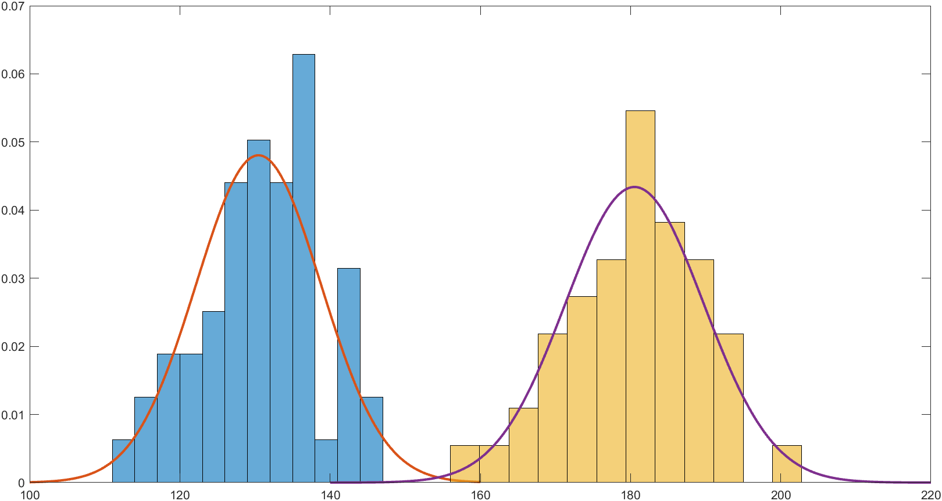

#### Load Simulated Hospital Data

% Clear workspace
clear
clc
% Load Data
load hospital.mat

#### Plot weights of the patients

Firstly, lets plot weight data

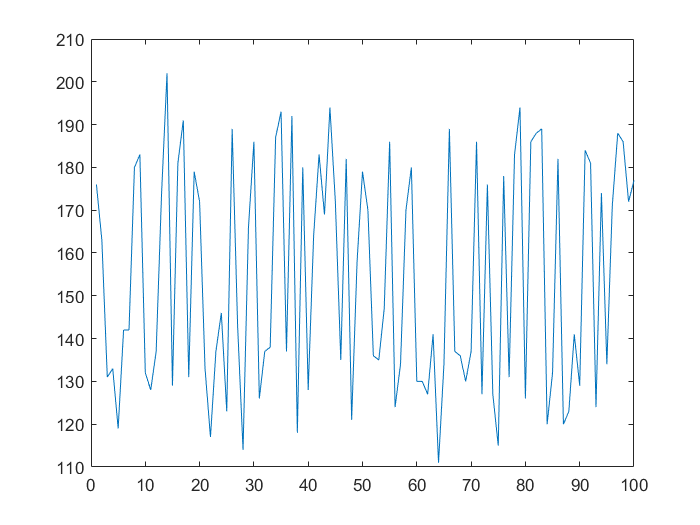

weightsAll=hospital.Weight;
plot(weightsAll)

When we analyze this plot we obtain no usefull information

#### Plot Histogram

Now, let's see the histogram

h1=histogram(weightsAll,'BinWidth',5)

h1 =   Histogram with properties:

             Data: [100×1 double]
           Values: [2 4 7 9 13 11 5 2 0 1 2 2 8 6 11 11 5 0 1]
          NumBins: 19
         BinEdges: [110 115 120 125 130 135 140 145 150 155 160 165 170 175 180 185 190 195 200 205]
         BinWidth: 5
        BinLimits: [110 205]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


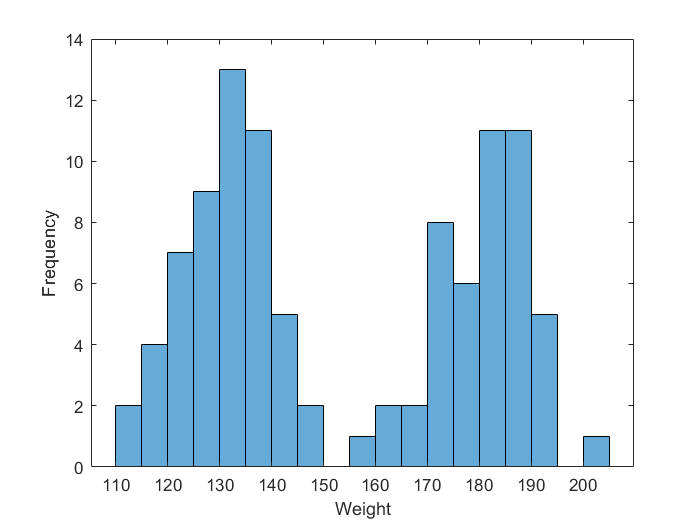

xlabel('Weight')
ylabel('Frequency')

Clearly we have two group of data. 

We can assume that gender makes difference in the data.

#### Split Data

So split this data by gender. Then plot the histograms for each gender.

weightFemale=hospital.Weight(hospital.Sex=='Female')

weightFemale =    131
   133
   119
   142
   142
   132
   128
   137
   129
   131


h2=histogram(weightFemale,'BinWidth',5)

h2 =   Histogram with properties:

             Data: [53×1 double]
           Values: [2 4 7 9 13 11 5 2]
          NumBins: 8
         BinEdges: [110 115 120 125 130 135 140 145 150]
         BinWidth: 5
        BinLimits: [110 150]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


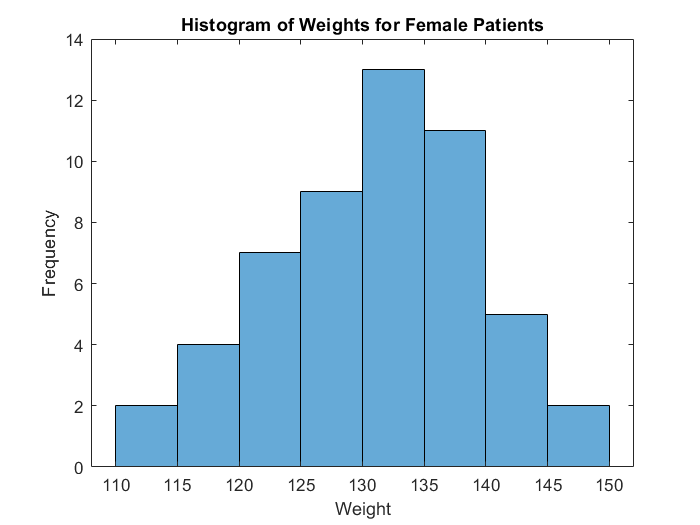

xlabel('Weight')
ylabel('Frequency')
title('Histogram of Weights for Female Patients')

weightMale=hospital.Weight(hospital.Sex=='Male')

weightMale =    176
   163
   180
   183
   174
   202
   181
   191
   179
   172


h3=histogram(weightMale,'BinWidth',5)

h3 =   Histogram with properties:

             Data: [47×1 double]
           Values: [1 2 2 8 6 11 11 5 0 1]
          NumBins: 10
         BinEdges: [155 160 165 170 175 180 185 190 195 200 205]
         BinWidth: 5
        BinLimits: [155 205]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  Show all properties


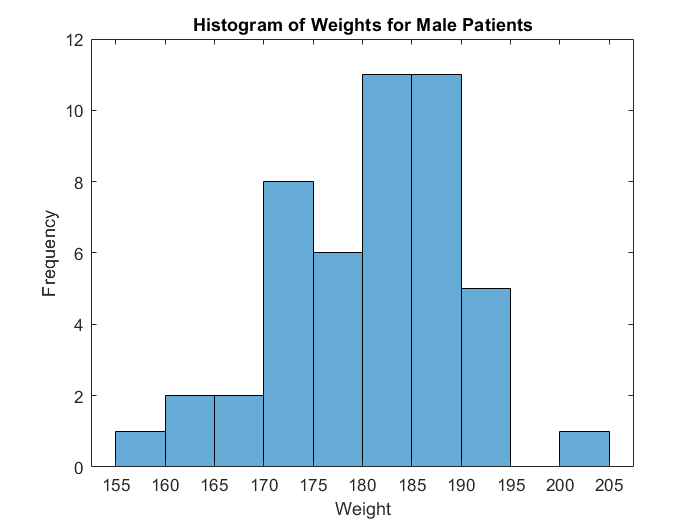

xlabel('Weight')
ylabel('Frequency')
title('Histogram of Weights for Male Patients')

#### Calculate std and mean values 

stdWeightFemale=std(weightFemale);
meanWeightFemale=mean(weightFemale);
stdWeightMale=std(weightMale);
meanWeightMale=mean(weightMale);

#### **Plot histograms and PDFs for both gender in the same figure.**

h4 = histogram(weightFemale,'Normalization','pdf',"FaceColor","yellow","BinWidth",5)

h4 =   Histogram with properties:

             Data: [53×1 double]
           Values: [0.0075 0.0151 0.0264 0.0340 0.0491 0.0415 0.0189 0.0075]
          NumBins: 8
         BinEdges: [110 115 120 125 130 135 140 145 150]
         BinWidth: 5
        BinLimits: [110 150]
    Normalization: 'pdf'
        FaceColor: [1 1 0]
        EdgeColor: [0 0 0]

  Show all properties


stdF = std(weightFemale)

stdF = 8.3034

meanF = mean(weightFemale)

meanF = 130.4717


hold on 
y = 100:0.1:160;
mu = meanF;
sigma = stdF;

f1 = exp(-(y-mu).^2./(2*sigma^2))./(sigma*sqrt(2*pi));
plot(y,f1,'LineWidth',1.5)

h5 = histogram(weightMale,'Normalization','pdf',"FaceColor","red","BinWidth",5)

h5 =   Histogram with properties:

             Data: [47×1 double]
           Values: [0.0043 0.0085 0.0085 0.0340 0.0255 0.0468 0.0468 0.0213 0 0.0043]
          NumBins: 10
         BinEdges: [155 160 165 170 175 180 185 190 195 200 205]
         BinWidth: 5
        BinLimits: [155 205]
    Normalization: 'pdf'
        FaceColor: [1 0 0]
        EdgeColor: [0 0 0]

  Show all properties


stdM = std(weightMale)

stdM = 9.1932

meanM = mean(weightMale)

meanM = 180.5319

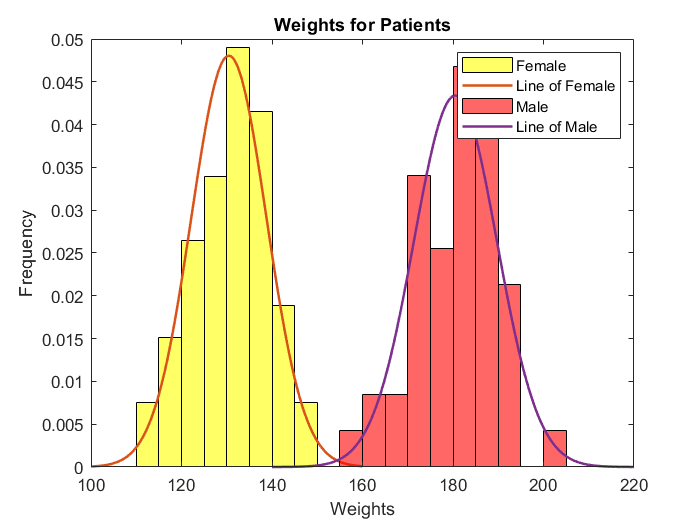


y2 = 140:0.1:220;
mu2 = meanM;
sigma2 = stdM;

f2 = exp(-(y2-mu2).^2./(2*sigma2^2))./(sigma2*sqrt(2*pi));
plot(y2,f2,'LineWidth',1.5)
legend("Female","Line of Female","Male","Line of Male")
xlabel("Weights")
ylabel("Frequency")
title("Weights for Patients")

# Finally, export this file as pdf by clicking Save->Export to PDF